clear; clear path; clc;
cd('~/git/hardDiskControl/continuousTimeControl/distReject/')
load('../../data/plantTF.mat');
addpath ../../funcs/;

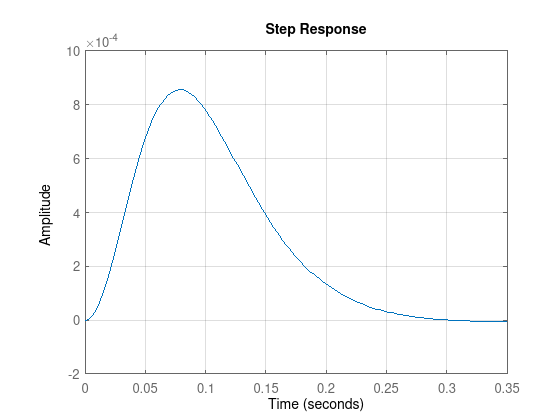

Ps;
P = 1000;
I = 10000;
D = 40;
N = 100;
Cs = pidGen(P,I,D,N,1);
controlledDist = Ps/(1+Cs*Ps);

step(controlledDist); grid on;



poles = distPoles(P,I,D,N)

poles = 1.0e+02 *

  -0.1826 - 0.1070i
  -0.1826 + 0.1070i
  -0.3193 - 0.3498i
  -0.3193 + 0.3498i
  -0.9980 - 9.9246i
  -0.9980 + 9.9246i


wn = abs(poles)

wn =    21.1661
   21.1661
   47.3655
   47.3655
  997.4649
  997.4649


damps = calcDamp(poles)

damps =    -0.5055
    0.5055
   -0.7385
    0.7385
   -0.9950
    0.9950
